# LSTM

Le reti neurali LSTM (**Long Short-Term Memory**) sono un tipo di rete  neurale ricorrente (RNN) progettata per catturare le dipendenze a lungo  termine nei dati sequenziali. A differenza delle reti neurali  feedforward tradizionali, le LSTM sono in grado di mantenere e  utilizzare informazioni provenienti da osservazioni precedenti della sequenza. Le** LSTM sono particolarmente utili per l'identificazione di modelli non lineari in quanto possono catturare relazioni complesse e dipendenze  temporali nei dati**. Queste reti sono ampiamente utilizzate in  diverse applicazioni, come il riconoscimengto vocale, la traduzione automatica e l'analisi del testo.

La caratteristica distintiva delle LSTM risiede nelle sue "unità di  memoria" o "**celle di memoria**". Ogni cella di memoria contiene tre  componenti principali: un'unità di input, un'unità di output e una porta di cancellazione. Le porte delle LSTM includono:

- Porta di input: determina quanto delle nuove informazioni deve essere incorporato nella cella di memoria.

- Porta di output: determina quanto della cella di memoria deve essere esposto come output della rete.

- Porta di cancellazione: controlla quanto della memoria precedente deve essere dimenticato;ogni tot istanti di tempo si verifica se le vecchie informazioni sono ancora utili o possono essere cancellate

Queste porte consentono alle LSTM di imparare a memorizzare le  informazioni rilevanti per un determinato contesto e a dimenticare  quelle meno importanti

Nei **processi non lineari il fattore memoria è fondamentale,**  in particolar modo, in un contesto come quello del ph Neutralization, **il pH corrente** potrebbe **dipendere** non solo dai valori correnti dei reagenti ma anche **dai** loro **valori** passati** a causa della cinetica chimica coinvolta nel processo di neutralizzazione.** 

clc
clear all
close

Carichiamo i dati dal file `phdata.dat` e li assegniamo alle variabili `u1`, `u2` e `y:`

% Caricamento dei dati
data = load('phdata.dat');
% Estrazione degli ingressi e delle uscite
u1 = data(:, 2);
u2 = data(:, 3);
y = data(:, 4);

% Creazione della matrice
X = [u1 u2];    % colonne
T = y;         % riga

% Normalizzazione dei dati
X = normalize(X);
T = normalize(T);

La funzione *normalize()* viene utilizzata per normalizzare i dati in modo che abbiano una scala comparabile. Consiste nel trasformare i dati in modo che abbiano una media di zero e  una deviazione standard di uno, al fine di  rendere i dati più gestibili e facilitare il processo di addestramento  della rete neurale.

%Convertire i dati
X = double(X);
T = double(T);

L'architettura della rete LSTM è composta da quattro layer:

- *sequenceInputLayer(numFeatures)*: Questo layer rappresenta l'input della sequenza ed è configurato con il numero variabili in ingresso *numFeatures*. L'oggetto *sequenceInputLayer* definisce l'input come una sequenza di dati.

- *lstmLayer(numHiddenUnits)*: Questo layer è configurato con il numero di neuroni nascosti nel layer nascosto *numHiddenUnits*. Questo layer determina le dipendeze tra i dati. Il numero di unità nascoste corrisponde alla quantità di informazioni che il livello ricorda tra le fasi temporali (lo stato nascosto), se il numero di unità nascoste è troppo grande il livello potrebbe adattarsi eccessivamente ai dati di addestramento.

- *fullyConnectedLayer(num)*: Questo layer rappresenta un layer completamente connesso e  con una singola uscita. È utilizzato per aggregare le informazioni dalla LSTM e produrre un output finale. È un layer con neuroni connessi con tutta la rete. L'input di questa fully connected layer viene moltiplicato per dei pesi, ed in seguito sul prodotto viene applicata una funzione di trasformazione non lineare, mediante una fuinzione di attivazione non lineare.

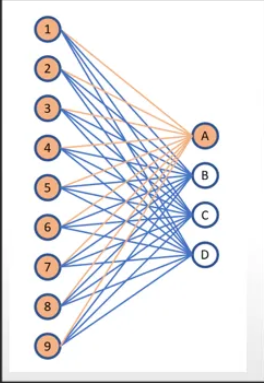

- *regressionLayer*: Questo layer rappresenta il layer di regressione finale, che calcola l'errore tra l'output della rete e l'output atteso. Il regression layer è generalmente posizionato alla fine di una rete neurale ed è responsabile della generazione dell'output numerico. Esso prende in input i valori calcolati dai precedenti strati della rete neurale e restituisce un valore numerico che rappresenta la previsione del modello.

% Definizione dell'architettura della rete LSTM
numFeatures = size(X, 2);
numHiddenUnits = 10;

% La rete creata sarà formata da 4 layer ciascuno specificato come segue
layers = [
    sequenceInputLayer(numFeatures) % il parametro specifica il numero di input
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)          % il parametro stabilisce quanti fullyConnectedLayer deve avere la rete (in questo caso 1)
    regressionLayer
];

Le opzioni di addestramento vengono configurate attraverso l'oggetto *options* utilizzando la funzione *trainingOptions*`:`

% Impostazione delle opzioni di addestramento
options = trainingOptions('adam', ...                   
    'MaxEpochs', 200, ...                             
    'MiniBatchSize', 64, ...                         
    'Shuffle', 'every-epoch', ...                       
    'Verbose', false, ...                                
    'Plots', 'none');                      

- '*adam*': L'algoritmo di ottimizzazione utilizzato durante l'addestramento; un algoritmo di ottimizzazione basato sul gradiente stocastico

- '*MaxEpochs*': specifica il numero massimo di epoche di addestramento; 

- '*MiniBatchSize*': specifica dimensione del mini-batch utilizzata durante l'addestramento → Un mini-batch è un gruppo di campioni di addestramento selezionati casualmente dal set di dati completo. Invece di calcolare l'errore e aggiornare i pesi della rete per ogni singolo campione di addestramento, viene calcolato l'errore medio del mini-batch e gli aggiornamenti dei pesi vengono applicati una volta per ogni mini-batch. 

- '*Shuffle*': specifica di mescolare i campioni di addestramento prima di ogni epoca;

- '*Verbose*' = false: non verranno mostrate le informazioni di output durante l'addestramento;

- '*Plots*': specifica di creare un grafico di progresso dell'addestramento. Specificando '*training-progress*' verrà stampato il grafico, specificando '*none*' non verrà visualizzato nessun grafico

% Addestramento della rete neurale LSTM
net = trainNetwork(X', T', layers, options);

Dopo l'addestramento, viene eseguita una simulazione della rete neurale utilizzando i dati di addestramento. La funzione *predict* viene utilizzata per ottenere le predizioni della rete sulla base degli input `X`. Le predizioni vengono memorizzate nella variabile *y_sim*`.`

Vediamo come si comporta il modello identificato con gli stessi input, se l'uscita *y_sim* si avvicina all'uscita reale del sistema l'identificazione è buona.

% Simulazione della rete neurale LSTM
y_sim = predict(net, X')';

noise = 0.001*randn(length(T), 1);

Nei vari paper trovati, in cui si studiava la dinamica della neutralizzazione del Ph, veniva considerato un** rumore bianco gaussiano con media nulla e deviazione standard σ = 0.001**; per simulare la situazione più realistica di un rumore di misura.

In questo sezione di codice, vengono calcolati il coefficiente di correlazione e il Mean Squared Error (MSE) tra le uscite effettive *y* e le predizioni con rumore `(`*y_sim+noise*`)`

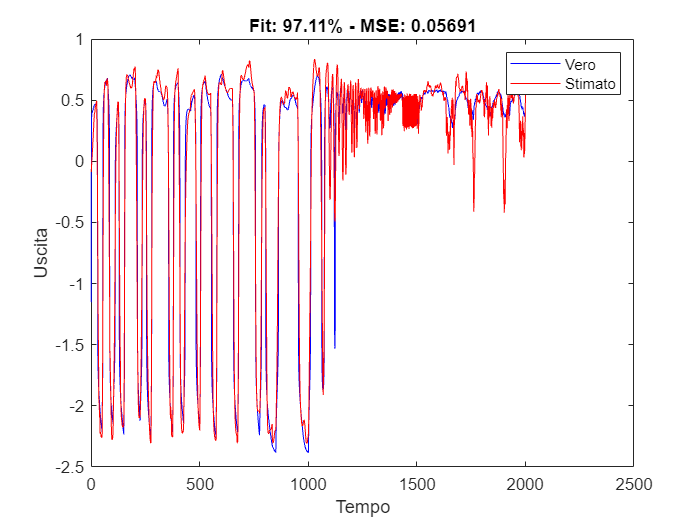

% Calcolo del coefficiente di correlazione
corr = corrcoef(T, (y_sim+noise));
fit_percent = corr(1, 2) * 100;

% Calcolo del Mean Squared Error (MSE)
mse_value = mse(T - (y_sim + noise));

% Visualizzazione dei risultati
figure
plot(T, 'b');
hold on;
plot(y_sim, 'r');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato');
title(['Fit: ' num2str(fit_percent, '%.2f') '% - MSE: ' num2str(mse_value)]);

% Visualizzazione del valore percentuale del fit e del MSE
fprintf('Valore percentuale del fit: %.2f%%\n', fit_percent);

Valore percentuale del fit: 97.11%


fprintf('MSE: %.6f\n', mse_value);

MSE: 0.056910


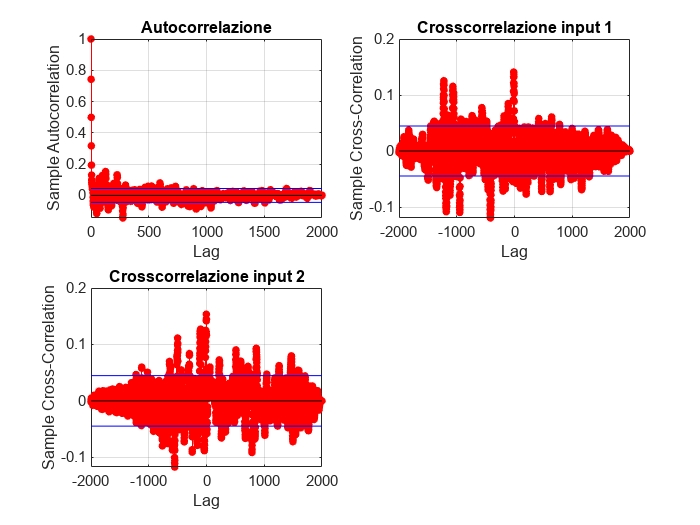

% Visualizzazione dei risultati
figure
subplot(2, 2, 1)
autocorr(T - double(y_sim), 'NumLags', length(T)-1);
title('Autocorrelazione');

subplot(2, 2, 2)
crosscorr(X(:,1) , T - double(y_sim), 'NumLags', length(T)-1);
title('Crosscorrelazione input 1');

subplot(2, 2, 3)
crosscorr(X(:,2) , T - double(y_sim), 'NumLags', length(T)-1);
title('Crosscorrelazione input 2');

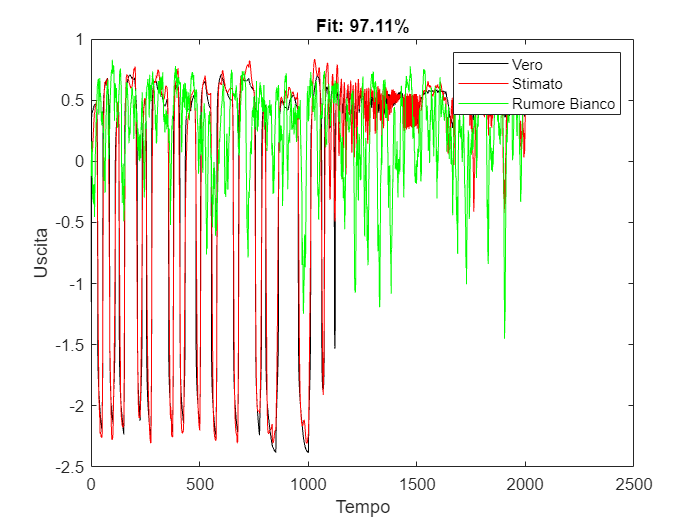

%% Bianchezza
noise = 0 + 1*randn(length(T), 2);
% noise = 0.001*randn(length(T), 2);

y_noise = predict(net, noise')';
std_noise = std(noise);
std_estimated = std(y_sim);

%clf(100)
%clf(200)

figure(100)
plot(T, 'k');
hold on;
plot(y_sim, 'r');
% plot(y_noise, 'g');
plot(y_noise, 'g');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato', 'Rumore Bianco');
title(['Fit: ' num2str(fit_percent, '%.2f') '%']);

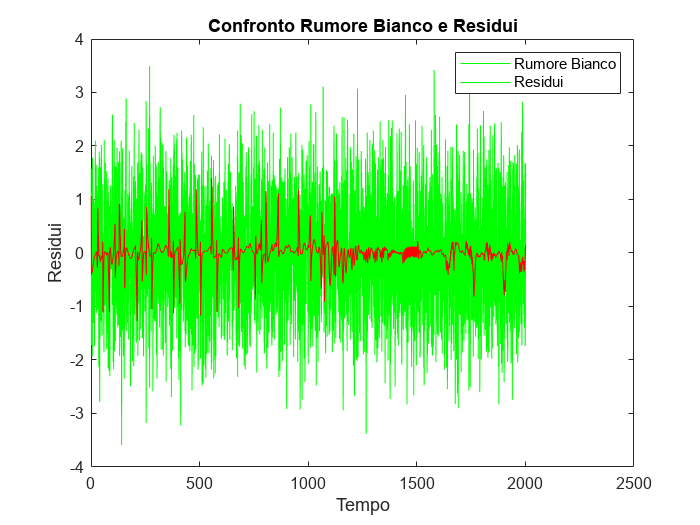

figure(200)
plot(noise, 'g');
hold on;
plot(y_sim - T, 'r');
xlabel('Tempo');
ylabel('Residui');
legend('Rumore Bianco', 'Residui');
title('Confronto Rumore Bianco e Residui');

%% Validazione incrociata (K-fold cross-validation)
K = 5; % Numero di fold
cvp = cvpartition(length(X), 'KFold', K);

fit_percentages = zeros(1, K);
for i = 1:K
    i                               % essendo il processo un po' lungo stampo l'indice 'i' per capire a che iterazione ci troviamo
    trainIdx = training(cvp, i);
    testIdx = test(cvp, i);
    
    X_train = X(trainIdx, :);
    T_train = T(trainIdx);
    
    X_test = X(testIdx, :);
    T_test = T(testIdx);
    
    % Addestramento della rete neurale LSTM
    net = trainNetwork(X_train', T_train', layers, options);
    
    % Simulazione della rete neurale LSTM sui dati di test
    y_test_sim = predict(net, X_test')';
    
    % Calcolo del coefficiente di correlazione
    corr = corrcoef(T_test, y_test_sim);
    fit_percent = corr(1, 2) * 100;
    
    fit_percentages(i) = fit_percent;
end
% Calcolo della media dei coefficienti di correlazione
mean_fit_percent = mean(fit_percentages);

% Visualizzazione dei risultati della validazione incrociata
fprintf('\nValidazione incrociata (K-fold cross-validation):\n');


Validazione incrociata (K-fold cross-validation):


fprintf('Fit percentuale medio: %.2f%%\n', mean_fit_percent);

Fit percentuale medio: 63.03%
